%% IV Drug Infusion Biomedical Simulation
% This script models drug concentration in blood during IV infusion using
% a pharmacokinetic differential equation.

%{
ES115 IV Drug Infusion Biomedical Simulation
 Created by Gracy Sylvestre - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-27


State the problem (Purpose):
 Electric bill costs are compared based on usage values to determine which bill would be most cost effective.

Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}


clear; clc; close all;     % Clear workspace

%user input
IR = input("Enter infusion rate (mg/hr), e.g., 50: ");  % rate in which drugs are being input
if isempty(IR) %if choice left empty -> default option
    IR = 50;
end

V = input("Enter blood volume (L), e.g., 5: ");%volume of patients blood
if isempty(V) %if choice left empty -> default option
    V = 5;
end

ER = input("Enter elimination rate (1/hr), e.g., 0.4: "); % rate of clearence
if isempty(ER) %if choice left empty -> default option
    ER = 0.4;
end

simTime = input("Enter simulation time (hours), e.g., 24: "); % time simulation is ran in total
if isempty(simTime) %if choice left empty -> default option
    simTime = 24;
end

timestep = 0.01;                     % Time step (hours)
time = 0:timestep:simTime;          % Time vector

%generate variables

C = zeros(size(time)); %array for drug concentration

safeMin = 8;% Minimum safe concentration (theraputic level)
safeMax = 20;%Maximum safe concentration

%create loop for simulation

for a = 2:length(time)
    
    % Pharmacokinetic equation
    dCtimestep = (IR/V) - ER*C(a-1); %concentration rate of change
    
    % Euler numerical integration
    C(a) = C(a-1) + dCtimestep*timestep;
    
    %negative concentration invalid (prevention)
    if C(a) < 0
        C(a) = 0;
    end
end

%metrics

maxC = max(C); % Peak concentration
avgC = mean(C);% Average concentration
timeToSteady = find(abs(diff(C)) < 0.0001, 1); 

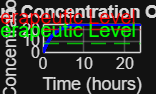

%visuals and graphs 

figure; %create new figure
plot(time, C, 'b', 'LineWidth', 2); % Plot concentration curve in blue
hold on;

yline(safeMin, '--g', 'Min Therapeutic Level'); % horizontal line representing Safe lower bound 
yline(safeMax, '--r', 'Max Therapeutic Level'); % horizontal line representing Safe upper bound

title("IV Drug Concentration Over Time"); %title the plot created
xlabel("Time (hours)"); %label the horizontal axis
ylabel("Drug Concentration (mg/L)"); %label the vertical axis
grid on;

%display results

fprintf("\n BIOMEDICAL RESULTS \n"); %display title of interpretation section


===== BIOMEDICAL RESULTS =====



fprintf("Peak Concentration: %.2f mg/L\n", maxC); %display max concentraion

Peak Concentration: 25.00 mg/L


fprintf("Average Concentration: %.2f mg/L\n", avgC);%display min concentraion

Average Concentration: 22.40 mg/L



%% Safety evaluation
if maxC > safeMax  %if max concentraion > max safe concentration
    fprintf("WARNING: Toxic concentration reached!\n"); %concentration has reached danger zone
elseif maxC < safeMin %if max concentraion < min safe concentration
    fprintf("WARNING: Sub-therapeutic dosing.\n"); %concentration has gone ineffective
else
    fprintf("Drug remains within safe therapeutic range.\n"); %concentration has reached safe range
end

%test sample rates
fprintf("\nTesting different elimination rates...\n");


Testing different elimination rates...



ERvalues = [0.2 0.4 0.6];  % Simulated patient variability

for E = ERvalues
    
    Ctest = zeros(size(time)); % Reset concentration
    
    for a = 2:length(time)
        dCtimestep_test = (IR/V) - E*Ctest(a-1);
        Ctest(a) = Ctest(a-1) + dCtimestep_test*timestep;
    end
    
    fprintf("ER = %.1f → Max Concentration = %.2f mg/L\n", E, max(Ctest)); %display  energy rate and max concentration given samples
end

ke = 0.2 → Max Concentration = 49.59 mg/L
ke = 0.4 → Max Concentration = 25.00 mg/L
ke = 0.6 → Max Concentration = 16.67 mg/L


%final thoughts & discussions
fprintf("\nInterpretation:\n");


Interpretation:


fprintf("- Higher infusion rates increase risk of toxicity.\n");

- Higher infusion rates increase risk of toxicity.


fprintf("- Higher elimination rates reduce drug effectiveness.\n");

- Higher elimination rates reduce drug effectiveness.


fprintf("- Proper dosing must balance infusion and clearance rates.\n");

- Proper dosing must balance infusion and clearance rates.


fprintf("- This model helps design safe IV drug delivery systems.\n");

- This model helps design safe IV drug delivery systems.
